x5 = 1;


Figure = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);
% Create axes
axes1 = axes('Parent',Figure);
hold(axes1,'on');
for x5 = 1:n
plot1 = plot(Tx(:,x5),htcx(:,x5),'Parent',axes1,'LineWidth',2);
set(plot1(1),'DisplayName',string(NAME(x5)));
x5 = x5+1;
end

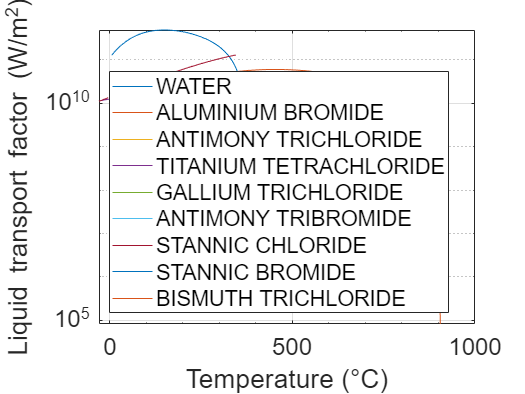

%set(plot1(1),'DisplayName','');

% Create ylabel
ylabel({'Liquid transport factor (W/m^2)'});

% Create xlabel
xlabel({'Temperature (°C)'});

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[250 550]);
box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorTick','on','YGrid','on',...
    'YMinorTick','on','YScale','log');
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','southwest');